# TALLER MATLAB

### PUNTO 1

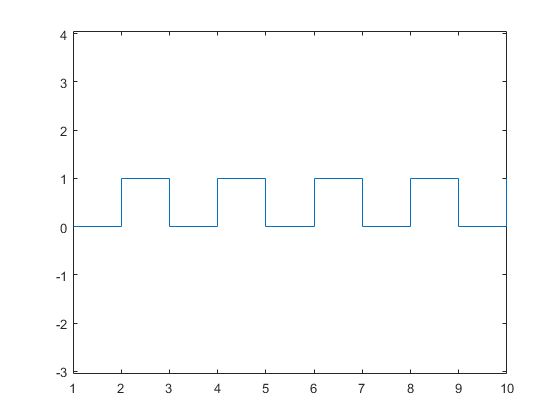

clf
 
%Se define el vector h para el eje y (valores señal)
%The y axis vector h (signal values) is defined 
h = [ 0 1 0 1 0 1 0 1 0 1 ];
%Se define el vector de los valores para el eje x (tiempo)
%The x axis vector x (time) is defined 
x = [ 1 2 3 4 5 6 7 8 9 10 ];
%Se hace la gráfica con la función stairs relacionando el tiempo con los valores de la señal 
%Using the stairs function the graph between the x and h vectors is plotted
stairs(x,h)
%Se definen los valores de los ejes para que la grafica se muestre a una escala visualmente mejor
%The values of the axis are defined so that the graph looks better
axis equal 

### PUNTO 2

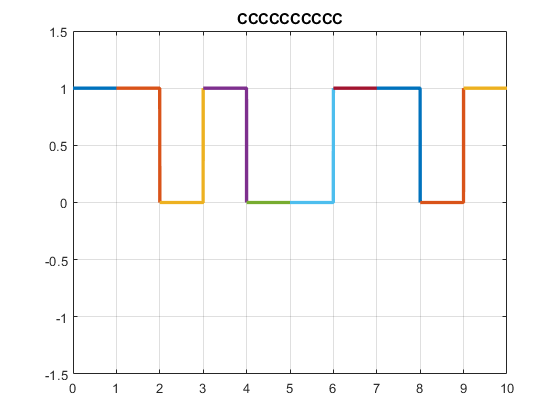

clf
 
%Se define el vector h de valores para el eje y (valores señal)
%The vector h for the values of the y axis (signal values)
h=[1 1 0 1 0 0 1 1 0 1];
%Se define la variable incial para el ciclo while
%The initial variable for the while cicle is defined
n=1;
%Se da al vector h un valor de 1 en la posición 11 para evitar un error en uno de los if.
%The vector h gets a value of 1 assigned on the 11th position to avoid a mistake on one of the if's.
h(11)=1;
%Se inicia el ciclo while para n menor o igual a 10 para recorrer las posiciones del vector h.
%The while cicle is started for n equal or less than 10 in order to go through the positions of the h vector.
while n<=10;
%Se crea el vector t de n-1 hasta n con paso de 0.001
%The vector t from n-1 to n with 0.001 steps is created
t=n-1:0.001:n;
%Se hace un condicional if al que se entra cuando el vector h en la posición n toma el valor de 0
%An if conditional is created with the condition of the vector h in the n position taking the value of 0
if h(n) == 0
%Se realiza un nuevo if dentro del anterior al que se entra si el valor del vector h en la posicion n+1 es igual a 0
%An if inside the if is created with the condition of the vector h in the position n+1 taking the value of 0
if h(n+1)==0
%Se asigna a y un valor de t mayor a n
%y is asigned a value of t greater than n
y=(t>n);
%Se da la condicion contraria al segundo if
%The else condition for the second if is created
else
%Se asigna a y un valor de t igual a n
%y is asigned a value of t greater equal to n
y=(t==n);
%Se finaliza el segundo condicional if 
%The second if conditional is ended
end
%Se realiza la asignacion a d dandole a graficar t con y, dandole titulo a la grafica y activando la cuadricula de la misma.
%d gets assigned the graph of t with y, the graph is given a title and gets the grid on
d=plot(t,y); title ('DDDDDDDDDD');grid on;
%Se define en 2.5 el ancho de las lineas para la grafica d
%The width for the d graph lines is set to 2.5
set(d,'LineWidth',2.5);
%Se usa el comando hold on para mantener el estado de la grafica
%With the hold on command the graph status is mantained
hold on;
%Se definen los limites de los ejes de la grafica para x de 0 a 10 y para y de -1.5 a 1.5
%The axis limits for the graph are defined for x from 0 to 10 and for y from -1.5 to 1.5
axis([0 10 -1.5 1.5]);
%Se da la condicion contraria al primer if
%The else condition for the first if is given
else
%Se crea un if dentro de la condicion contraria del primer if al que se entra cuando el vector h en la posicion n+1 es igual a 0
%An if is created inside the else with the condition of the vector h in the position n+1 being equal to 0
if h(n+1)==0
%Se le asigna a y un valor de t menor a n y se le resta la multiplicacion de 0 por t igual a n
%y gets asigned a value of t less than n minus 0 times t equal to n
y=(t<n)-0*(t==n);
%Se inicia la condicion contraria del tercer if
%The else condition for the third if is started
else
%Se le asigna a y un valor de t menor a n y se le resta la multiplicacion de 1 por t igual a n
%y gets asigned a value of t less than n plus 1 times t equal to n
y=(t<n)+1*(t==n);
%Se termina el tercer if
%The tthird if is ended
end
%Se realiza la asignacion a d dandole a graficar t con y, dandole titulo a la grafica y activando la cuadricula de la misma.
%d gets assigned the graph of t with y, the graph is given a title and gets the grid on
d=plot(t,y);title('CCCCCCCCCC');grid on;
%Se define en 2.5 el ancho de las lineas para la grafica d
%The width for the d graph lines is set to 2.5
set(d,'LineWidth',2.5);
%Se usa el comando hold on para mantener el estado de la grafica
%With the hold on command the graph status is mantained
hold on;
%Se definen los limites de los ejes de la grafica para x de 0 a 10 y para y de -1.5 a 1.5
%The axis limits for the graph are defined for x from 0 to 10 and for y from -1.5 to 1.5
axis([0 10 -1.5 1.5]);
%Se finaliza el primer condicional if
%The first if conditional ends
end
%Se suma 1 al valor de n
%n gets added 1
n=n+1;
%Se finaliza el ciclo while
%The while loop is ended
end

### PUNTO 3

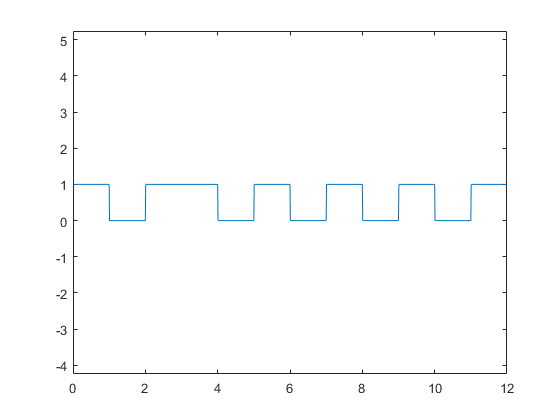

clf
 
%Se describe la trama a evaluar
%The plot to evaluate is described
trama=[1 0 1 1 0 1 0 1 0 1 0 1 ];
%Se describe el vector de tiempo (x)
%The time vector x is described
x=0:.01:length(trama);
%Se crea el vector resultado con el tamaño del primer valor de la trama
%The result vector is created with the size of the first plot
resultado=[trama(1)];
for i=1:length(trama)
    %Se realiza la evaluación del valor de la trama en la posición i, para ver si es igual a 0
    %The plot value is analyzed in position i to see if it's equal to 0
    if trama(i)==0
        %Si el valor de la trama es 0 entonces en el vector de resultados se llenará con ceros
        %If the value of the plot is 0, then the results vector is filled with zeros
        resultado=[resultado,(zeros(1,100))];
    end
    %Se realiza la evaluación del valor de la trama en la posición i, para ver si es igual a 1
    %The plot is analyzed in the position i to see if it's equal to 1
    if trama(i)==1
        %Si el valor de la trama es 1 entonces en el vector de resultados se llenará con unos
        %If the value of the plot is 1, then the results vector is filled with ones
        resultado=[resultado,ones(1,100)];
    end
    %Se incrementará el valor de i para evaluar cada valor de la trama
    %The value of i is increased to evaluate each value of the plot
    i=i+1;
end
%Se grafica el resultado vs el tiempo establecido para poder ver el tren de pulsos
%The result vs time graph is done to see the pulse train
plot(x,resultado)
%Se definen los valores de los ejes para que la gráfica se muestre a una escala visualmente mejor
%The values of the axis are defined so that the graph looks better
axis equal

### PUNTO 4

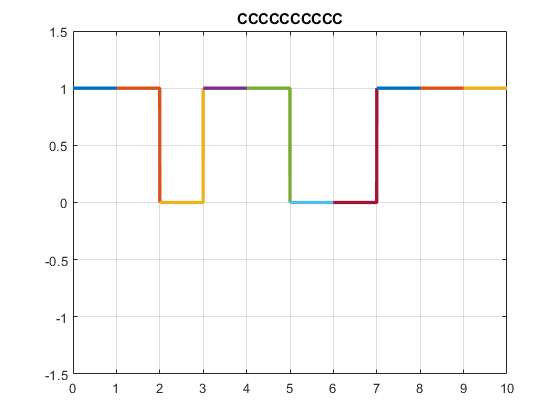

 clf
  
 h=round(rand(1,11));
 n=1;
 h(11)=1;
 while n<=10;
 t=n-1:0.001:n;
 if h(n) == 0
 if h(n+1)==0
 y=(t>n);
 else
 y=(t==n);
 end
 d=plot(t,y); title ('DDDDDDDDDD');grid on;
 set(d,'LineWidth',2.5);
 hold on;
 axis([0 10 -1.5 1.5]);
 else
 if h(n+1)==0
 y=(t<n)-0*(t==n);
 else
 y=(t<n)+1*(t==n);
 end
 d=plot(t,y);title('CCCCCCCCCC');grid on;
 set(d,'LineWidth',2.5);
 hold on;
 axis([0 10 -1.5 1.5]);
 end 
 n=n+1;
 end

### PUNTO 5

clf

UNRZ because when we carry out the analysis of the code we see that the  graph takes values ��of 1 when we want to show a one and 0 when we want to show zero.

### PUNTO 6

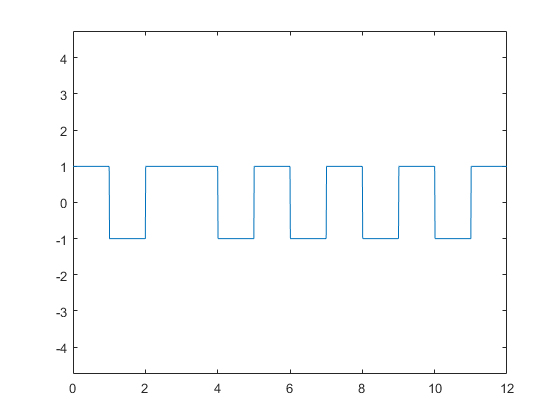

clf
 
% Se describe la trama a evaluar
%The plot to evaluate is described
trama=[1 0 1 1 0 1 0 1 0 1 0 1 ];
% Se describe el vector de tiempo (x)
%The time vector x is described
x=0:.01:length(trama);
% Se crea el vector resultado con el tamaño del primer valor de la trama
%The result vector is created with the size of the first plot
resultado=[trama(1)];
for i=1:length(trama)
    % Se realiza la evaluación del valor de la trama en la posición i, para ver si es igual a 0
    %The plot value is analyzed in position i to see if it's equal to 0
    if trama(i)==0
        % Si el valor de la trama es 0 entonces se multiplicará por -1 cada valor de uno para realizar el sistema de tren de pulsos bipolar
        % If the value of the plot is 0 then each value of one will be multiplied by -1 to make the bipolar pulse train system
        resultado=[resultado,(-1.*ones(1,100))];
    end
        % Se realiza la evaluación del valor de la trama en la posición i, para ver si es igual a 1
        %The plot is analyzed in the position i to see if it's equal to 1
    if trama(i)==1
        % Si el valor de la trama es 1 entonces en el vector de resultados se llenará con unos
        % If the value of the plot is 1 then the result vector is filled with ones
        resultado=[resultado,ones(1,100)];
    end
    % Se incrementará el valor de i para evaluar cada valor de la trama
    % The value of i is increased to evaluate each value of the plot
    i=i+1;
end
% Se grafica el resultado vs el tiempo establecido para poder ver el tren de pulsos
%The result vs time graph is done to see the pulse train
plot(x,resultado)
% Se definen los valores de los ejes para que la gráfica se muestre a una escala visualmente mejor
%The values of the axis are defined so that the graph looks better
axis equal